clear;
clc;

% Cargar datos del archivo
filename = 'UCS_Satellite_Database.txt';  

% Buscar la posición de la columna llamada 'Eccentricity'
opts = detectImportOptions(filename, 'Delimiter', '\t'); 
ecc_col = find(strcmpi(opts.VariableNames, 'Eccentricity'));
if isempty(ecc_col)
    error('No se encontró una columna llamada "Eccentricity". Revisa el nombre exacto.');
end
opts.SelectedVariableNames = opts.VariableNames{ecc_col};

% Carga los datos de la columna seleccionada como tabla
ecc_data = readtable(filename, opts);
eccentricities = ecc_data{:,1};
eccentricities = eccentricities(eccentricities < 1);

% Calcular el total de satélites con excentricidad entre 0 y 0.01 (incluidos)
num_ecc_0_001 = sum(eccentricities >= 0 & eccentricities <= 0.01);

% Calcular el número total de satélites con excentricidad válida
num_total_sat = numel(eccentricities);

% Calcular el porcentaje
percentage = (num_ecc_0_001 / num_total_sat) * 100;

% Mostrar resultados en consola
fprintf('Número de satélites con excentricidad entre 0 y 0.01: %d\n', num_ecc_0_001);

Número de satélites con excentricidad entre 0 y 0.01: 7380


fprintf('Número total de satélites con excentricidad conocida: %d\n', num_total_sat);

Número total de satélites con excentricidad conocida: 7541


fprintf('Porcentaje de satélites con excentricidad entre 0 y 0.01: %.3f%\n', percentage);

Porcentaje de satélites con excentricidad entre 0 y 0.01: 97.865

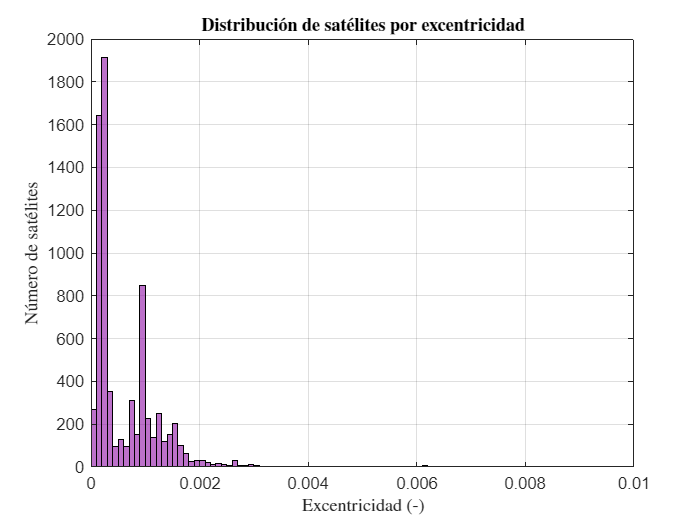


% Crear una nueva figura para el histograma
figure;
histogram(eccentricities, 'BinWidth', 0.0001, 'FaceColor', [0.56 0.07 0.65]);
xlabel('Excentricidad (-)', 'Interpreter', 'latex');
ylabel('N\''umero de sat\''elites', 'Interpreter', 'latex');
title('\bf{Distribuci\''on de sat\''elites por excentricidad}', 'Interpreter', 'latex');
xlim([0, 0.01])
grid on;